%EE415 - Term Project - Part 2
%Kerem Yakutlu - 2444107

Beams = 100; %Number of beams as an input.
Step_Size = deg2rad(1); %Specifying beams and step size, as an input.

**Test Image Projection**

In this code block, I have written how to project the test image.

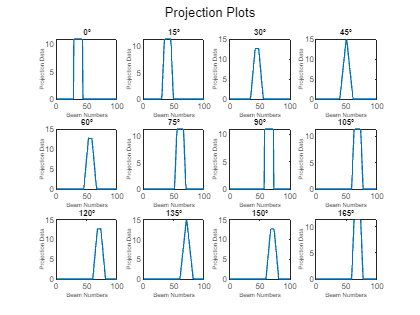

I = cell2mat(struct2cell(load('square.mat'))); %Loading the image, as an input.

Projection_of_the_Test_Image = Projector(I, Beams, Step_Size); %Using the projecting function for the test image.

%%%Plotting.

Plotting_the_Projections(Projection_of_the_Test_Image, Beams, Step_Size);

**Complex Image Projection**

In this code block, I have written how to project a more complex image.

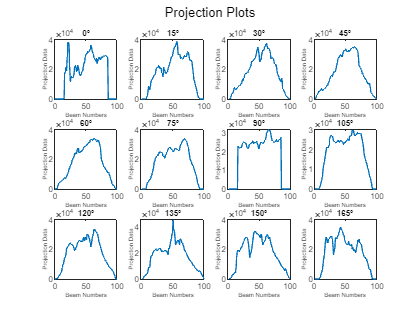

I = cell2mat(struct2cell(load('lena.mat'))); %Loading the image, as an input.

Projection_of_the_Complex_Image = Projector(I, Beams, Step_Size); %Using the projecting function for the test image.

%%%Plotting.

Plotting_the_Projections(Projection_of_the_Complex_Image, Beams, Step_Size);

**Test Image Backprojection (Unfiltered)**

In this code block, I have written how to backproject and filter the test image.

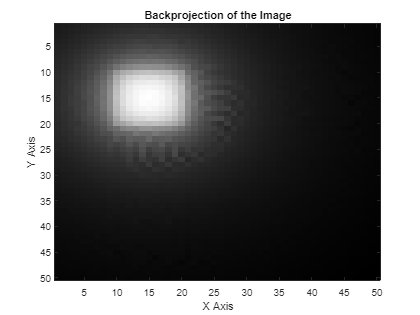

I = cell2mat(struct2cell(load('square.mat'))); %Loading the image, as an input.

Backprojection_of_the_Test_Image = Backprojector(I, Projection_of_the_Test_Image, Beams, Step_Size);

**Complex Image Backprojection (Unfiltered)**

In this code block, I have written how to backproject and filter the test image.

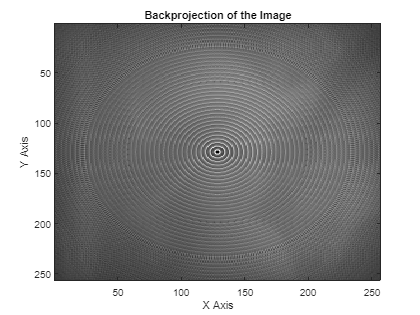

I = cell2mat(struct2cell(load('lena.mat'))); %Loading the image, as an input.

Backprojection_of_the_Complex_Image = Backprojector(I, Projection_of_the_Complex_Image, Beams, Step_Size);

**Test Image Filtered Backprojection**

In this code block, I have written how to backproject and filter the test image.

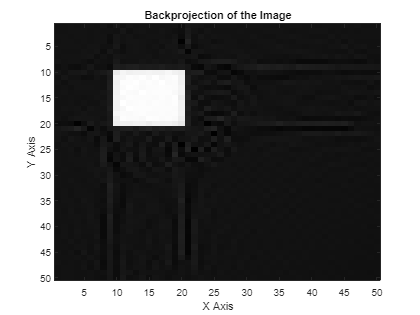

I = cell2mat(struct2cell(load('square.mat'))); %Loading the image, as an input.

Filtered_Projection_of_the_Test_Image = Filter(Projection_of_the_Test_Image);
Filtered_Backprojection_of_the_Test_Image = Backprojector(I, Filtered_Projection_of_the_Test_Image, Beams, Step_Size);

**Complex Image Filtered Backprojection (Triangular)**

In this code block, I have written how to backproject and filter the test image.

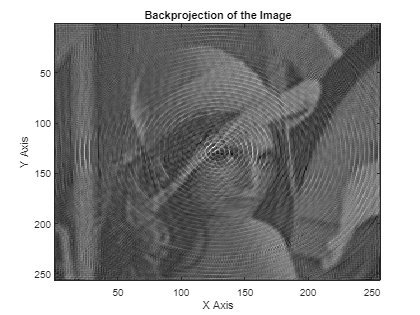

I = cell2mat(struct2cell(load('lena.mat'))); %Loading the image, as an input.

Filtered_Projection_of_the_Complex_Image = Filter(Projection_of_the_Complex_Image);
Filtered_Backprojection_of_the_Complex_Image = Backprojector(I, Filtered_Projection_of_the_Complex_Image, Beams, Step_Size);

**Functions for the Projection**

These are the functions for projection and plotting the sample images.

function [Projection_of_the_Image] = Projector(I, Beams, Step_Size) %Getting the image by taking the .mat form.
    [M , N] = size(I); %Taking the size of I, where M is the number of rows and N is the number of columns.
    
    t = linspace(-M/sqrt(2),M/sqrt(2),Beams); %Specifying t and theta by using linspace.
    theta = (0:Step_Size:(pi - Step_Size));
    
    Result_Matrix = zeros(length(theta), length(t)); %Obtaining the result matrix, which will be used after the back projection matrix.
    
    X_Index_Vector = linspace(-M/2,M/2,M+1); %Setting x vector for indexing.
    Y_Index_Vector = linspace(-M/2,M/2,M+1); %Setting y vector for indexing.
    
    %%%Calculating the functions.

    Radon_Transform_Function = @(t_value, theta_value, vector) ( t_value  - vector*cos(theta_value) ) / sin(theta_value); %Specialising the Radon Transform Function.
    
    Pythagorean_Equation = @(d_x, d_y) sqrt((d_x)^2 + (d_y)^2); %Specialising the Pythagorean Equation.

    Line_Integral_Function = @(Distance_Matrix_Element, Image, Row_Data_Element, Column_Data_Element) Distance_Matrix_Element * Image(Row_Data_Element, Column_Data_Element); %Specialising the Line Integral.


    for i = 1:length(t)
        for j = 1:length(theta)  
            Points_of_X = X_Index_Vector; %Straightforward appointing X values.
            %Points_of_Y = ( t(i) - X_Index_Vector*cos(theta(j)) ) / sin(theta(j)); %Calculating Y intersections for integer Y values
    
            Points_of_Y = Radon_Transform_Function(t(i), theta(j), X_Index_Vector);
            
            Lower_and_Higher_Values_Index_for_X = [];

            for k = 1:length(Points_of_Y)
                if (abs(Points_of_Y(k)) > M/2)
                    Lower_and_Higher_Values_Index_for_X = [Lower_and_Higher_Values_Index_for_X, k];
                end
            end

            Points_of_X(Lower_and_Higher_Values_Index_for_X) = [];
            Points_of_Y(Lower_and_Higher_Values_Index_for_X) = [];

            Points_of_X_First_Filtered = Points_of_X';
            Points_of_Y_First_Filtered = Points_of_Y';
            
            Combined_Vectors = [Points_of_X' Points_of_Y']; %Combining the vectors of X and Y.

            %%%%%%%%%%%%%%%%%%%%%%%%
    
            Points_of_Y = Y_Index_Vector; %Straightforward appointing X values.
            %Points_of_X = ( t(i) - Y_Index_Vector*sin(theta(j)) ) / cos(theta(j)); %Calculating X intersections for integer X values
    
            Points_of_X = Radon_Transform_Function(t(i), pi/2 - theta(j), Y_Index_Vector);

            Lower_and_Higher_Values_Index_for_Y = [];

            for k = 1:length(Points_of_X)
                if (abs(Points_of_X(k)) > M/2)
                    Lower_and_Higher_Values_Index_for_Y = [Lower_and_Higher_Values_Index_for_Y, k];
                end
            end

            Points_of_X(Lower_and_Higher_Values_Index_for_Y) = [];
            Points_of_Y(Lower_and_Higher_Values_Index_for_Y) = [];

            Points_of_X_Second_Filtered = Points_of_X';
            Points_of_Y_Second_Filtered = Points_of_Y';
    
            Recombined_Vector_for_Points_of_X = [Points_of_X_First_Filtered;Points_of_X_Second_Filtered]; %Double filtering the vectors, first filtering with respect to X and then, filtering with respect to Y.
            Recombined_Vector_for_Points_of_Y = [Points_of_Y_First_Filtered;Points_of_Y_Second_Filtered]; %We used this technique to clear the noise.
    
            Combined_Vectors = [Recombined_Vector_for_Points_of_X Recombined_Vector_for_Points_of_Y]; %Concentration of the vectors.

            %%%%%
    
            Coordinates_Sorted = unique(round(sortrows(Combined_Vectors,1),4),'rows'); %Row sorting for consecutive intersection points.
            
            L_Coordinates_Sorted = length(Coordinates_Sorted);

            Distance_Matrix = zeros(1,L_Coordinates_Sorted-1); %Creating distance vector, for calculation of projection (Projection Result = Square Value * Distance between Intersection Points) 
            Midpoints_X = zeros(1,L_Coordinates_Sorted-1); %Creating midpoint X and Y vectors
            Midpoints_Y = zeros(1,L_Coordinates_Sorted-1);
    

            for k = 1:(length(Coordinates_Sorted(:,1)) -1)
                   
    
                if (length(Coordinates_Sorted) == 1) %If there is only one coordinate set, the distance would be nothing but 0.
                    Distance_Matrix(k) = 0;
                    Midpoints_X(k) = 1;
                    Midpoints_Y(k) = 1;
                else
                    Distance_x = Coordinates_Sorted(k,1) - Coordinates_Sorted(k+1,1); %Taking the distances between x points.
                    Distance_y = Coordinates_Sorted(k,2) - Coordinates_Sorted(k+1,2); %Taking the distances between y points.
                    Distance_Matrix(k) = Pythagorean_Equation(Distance_x, Distance_y); %Writing the distance matrix with respect to the Pythagorean Equation.
                    Midpoints_X(k) = (2*Coordinates_Sorted(k+1,1) + Distance_x)/2;
                    Midpoints_Y(k) = (2*Coordinates_Sorted(k+1,2) + Distance_y)/2; %Finding the midpoints with the help of calculated distances
                end
            end
    
            Row_Data = M/2 - floor(Midpoints_Y);
            Column_Data = M/2 + ceil(Midpoints_X); %Row and column data must be positive for the sake of MATLAB indices. 

    
                for n = 1:length(Row_Data)
                    Result_Matrix(j,i) = Result_Matrix(j,i) + Line_Integral_Function(Distance_Matrix(n), I, Row_Data(n), Column_Data(n)); %Taking the line integral of projections. (Projection Result = Square Value * Distance between Intersection Points)
                end
    
        end

        Projection_of_the_Image = Result_Matrix;
    
end
end

function Plotting_the_Projections(Projection_of_The_Image, Beams, Step_Size) %Function for plotting the image.
    Place_Counter = 1; %Counter will be used in the for loop.
    figure;
    hold on;
    
    Theta_for_Plotting = (0:Step_Size:(pi - Step_Size)); %Theta angles are determined for the plotting.

    sgtitle("Projection Plots"); %Main title for the subplots.
    
    for m = round(1:length(Theta_for_Plotting)/12:length(Theta_for_Plotting))
        subplot(3,4,Place_Counter); %Subplots are used.
        plot(1:Beams,Projection_of_The_Image(m,:)) %Plotting every projection.
        title(num2str(rad2deg(Theta_for_Plotting(m))) + "°", FontSize=8); %Implementing the title.
        xlabel('Beam Numbers', FontSize=6); %Implementing the x label.
        ylabel('Projection Data', FontSize=6); %Implementing the y label.
        Place_Counter = Place_Counter + 1; %Counter is increased by 1 at every for loop iteration.
    end
    hold off;

end


**Functions for the Backprojection**

These are the functions for backprojection and plotting the sample images.

function [Backprojection_of_the_Image] = Backprojector(Image, Projection_of_the_Image, Beams, Step_Size) %Getting the image by taking the .mat form.
    [M, N] = size(Image); %Taking the size of the image.
    

    t = linspace(-M/sqrt(2),M/sqrt(2),Beams); %Specifying t and theta by using linspace.
    theta = (0:Step_Size:(pi - Step_Size));

    Back_Projection_Matrix = zeros(M,N); %Obtaining the back projection matrix to enter the back projection.
    
    X_Index_Vector = linspace(-M/2,M/2,M+1); %Setting x vector for indexing.
    Y_Index_Vector = linspace(-M/2,M/2,M+1); %Setting y vector for indexing.
    
    %%%Calculating the functions.

    Radon_Transform_Function = @(t_value, theta_value, vector) ( t_value  - vector*cos(theta_value) ) / sin(theta_value); %Specialising the Radon Transform Function.
    
    Pythagorean_Equation = @(d_x, d_y) sqrt((d_x)^2 + (d_y)^2); %Specialising the Pythagorean Equation.

    Line_Integral_Function_for_Backprojection = @(Distance_Matrix_Element, Projection_Matrix_Element) Distance_Matrix_Element * Projection_Matrix_Element; %Specialising the Line Integral.

    %%%Backprojection stage.

    for i = 1:length(t)
        for j = 1:length(theta)  
            Points_of_X = X_Index_Vector; %Straightforward appointing X values.
    
            Points_of_Y = Radon_Transform_Function(t(i), theta(j), X_Index_Vector);

            Lower_and_Higher_Values_Index_for_X = [];

            for k = 1:length(Points_of_Y)
                if (abs(Points_of_Y(k)) > M/2)
                    Lower_and_Higher_Values_Index_for_X = [Lower_and_Higher_Values_Index_for_X, k];
                end
            end

            Points_of_X(Lower_and_Higher_Values_Index_for_X) = [];
            Points_of_Y(Lower_and_Higher_Values_Index_for_X) = [];
            
            Combined_Vectors = [Points_of_X' Points_of_Y']; %Combining the vectors of X and Y.

   
            %%%%%%%%%%%%%%%%%%%%%%%%
    
            Points_of_Y = Y_Index_Vector; %Straightforward appointing X values.
    
            Points_of_X = Radon_Transform_Function(t(i), pi/2 - theta(j), Y_Index_Vector);

            Lower_and_Higher_Values_Index_for_Y = [];

            for k = 1:length(Points_of_X)
                if (abs(Points_of_X(k)) > M/2)
                    Lower_and_Higher_Values_Index_for_Y = [Lower_and_Higher_Values_Index_for_Y, k];
                end
            end

            Points_of_X(Lower_and_Higher_Values_Index_for_Y) = [];
            Points_of_Y(Lower_and_Higher_Values_Index_for_Y) = [];
    
            Recombined_Vector_for_Points_of_X = [Combined_Vectors(:,1);Points_of_X']; %Combining another set of vectors.
            Recombined_Vector_for_Points_of_Y = [Combined_Vectors(:,2);Points_of_Y'];
    
            Combined_Vectors = [Recombined_Vector_for_Points_of_X Recombined_Vector_for_Points_of_Y]; %Concentration of the vectors.
    
            %%%%%
            
            Coordinates_Sorted = unique(round(sortrows(Combined_Vectors,1),4),'rows'); %Row sorting for consecutive intersection points.
            
            L_Coordinates_Sorted = length(Coordinates_Sorted);

            Distance_Matrix = zeros(1,L_Coordinates_Sorted-1); %Creating distance vector, for calculation of projection (Projection Result = Square Value * Distance between Intersection Points) 
            Midpoints_X = zeros(1,L_Coordinates_Sorted-1); %Creating midpoint X and Y vectors
            Midpoints_Y = zeros(1,L_Coordinates_Sorted-1);
    

            for k = 1:(length(Coordinates_Sorted(:,1)) -1)
                   
    
                if (length(Coordinates_Sorted) == 1) %If there is only one coordinate set, the distance would be nothing but 0.
                    Distance_Matrix(k) = 0;
                    Midpoints_X(k) = 1;
                    Midpoints_Y(k) = 1;
                else
                    Distance_x = Coordinates_Sorted(k,1) - Coordinates_Sorted(k+1,1); %Taking the distances between x points.
                    Distance_y = Coordinates_Sorted(k,2) - Coordinates_Sorted(k+1,2); %Taking the distances between y points.
                    Distance_Matrix(k) = Pythagorean_Equation(Distance_x, Distance_y); %Writing the distance matrix with respect to the Pythagorean Equation.
                    Midpoints_X(k) = (2*Coordinates_Sorted(k+1,1) + Distance_x)/2;
                    Midpoints_Y(k) = (2*Coordinates_Sorted(k+1,2) + Distance_y)/2; %Finding the midpoints with the help of calculated distances
                end
            end
    
            Row_Data = M/2 - floor(Midpoints_Y);
            Column_Data = M/2 + ceil(Midpoints_X); %Row and column data must be positive for the sake of MATLAB indices. 

    
            for n = 1:length(Row_Data)
              R = Row_Data(n);
              C = Column_Data(n);
              Back_Projection_Matrix(R,C) = Back_Projection_Matrix(R,C) + Line_Integral_Function_for_Backprojection(Distance_Matrix(n), Projection_of_the_Image(j,i)); %Taking the line integral of projections. (Projection Result = Square Value * Distance between Intersection Points)
           end
    
        end

        Backprojection_of_the_Image = Back_Projection_Matrix;
    
    end

figure;
imagesc(Backprojection_of_the_Image);
title("Backprojection of the Image");
xlabel("X Axis");
ylabel("Y Axis")
colormap gray;
end

**Functions for the Filtering**

These are the functions for filtering and plotting the sample images.

function [Filtered_Projection] = Filter(Projection_of_the_Image) %Getting the image by taking the .mat form.
DFT_of_Projection = fft2(Projection_of_the_Image); %Getting the 2D FFT of the projection.
[Number_of_Angles, Number_of_Beams] = size(Projection_of_the_Image);  %Taking the size of the projection of the image.
Filtered_DFT_of_Projection = zeros(size(Projection_of_the_Image)); %Adjusting the filtered DFT matrix.
for i = 1:180
    Filtered_DFT_of_Projection(i,:) = DFT_of_Projection(i,:) .* triang(Number_of_Beams)'; %Using the triangular filter.
end
IFFT_of_Filtered_DFT_of_Projection = real(ifft2(Filtered_DFT_of_Projection)); %Getting the IFFT of the filtered FFT.
Filtered_Projection = IFFT_of_Filtered_DFT_of_Projection;
end